goal=@Fun;
con=@nonlincon;
options=optimoptions('gamultiobj');
options.Generations=50000;
options.MaxStallGenerations=10000;
options.FunctionTolerance=0.0001

options =   gamultiobj 选项:

   设置属性:
          FunctionTolerance: 1.0000e-04
             MaxGenerations: 50000
        MaxStallGenerations: 10000

   默认属性:
        ConstraintTolerance: 1.0000e-03
                CreationFcn: @gacreationuniform
               CrossoverFcn: @crossoverintermediate
          CrossoverFraction: 0.8000
                    Display: 'final'
         DistanceMeasureFcn: {@distancecrowding  'phenotype'}
                  HybridFcn: []
    InitialPopulationMatrix: []
     InitialPopulationRange: []
        InitialScoresMatrix: []
                    MaxTime: Inf
                MutationFcn: @mutationadaptfeasible
                  OutputFcn: []
             ParetoFraction: 0.3500
                    PlotFcn: []
             PopulationSize: '50 when numberOfVariables <= 5, else 200'
             PopulationType: 'doubleVector'
               SelectionFcn: {@select

%options = gaoptimset('paretoFraction',0.4,'populationsize',200,'generations',300,'stallGenLimit',200,'TolFun',1e-10);
[x,fval]=gamultiobj(goal,2,[1,-1],[0],[],[],[0,0],[1,1],con);

Optimization terminated: average change in the spread of Pareto solutions less than options.FunctionTolerance.


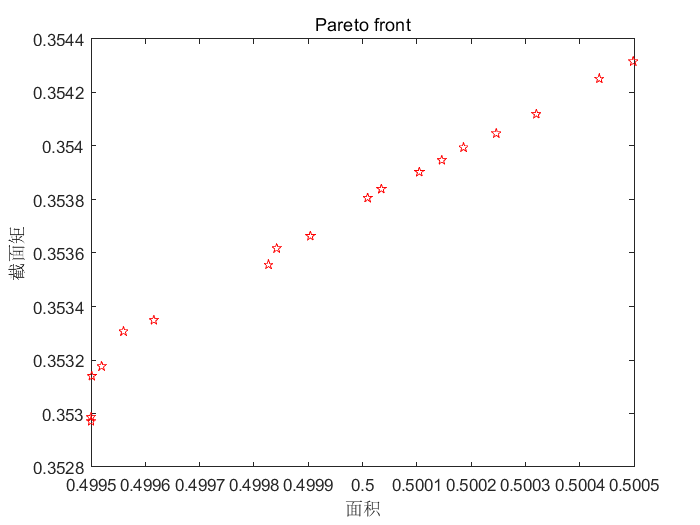

plot(fval(:,1),-fval(:,2),'pr')
xlabel('面积')
ylabel('截面矩')
title('Pareto front')

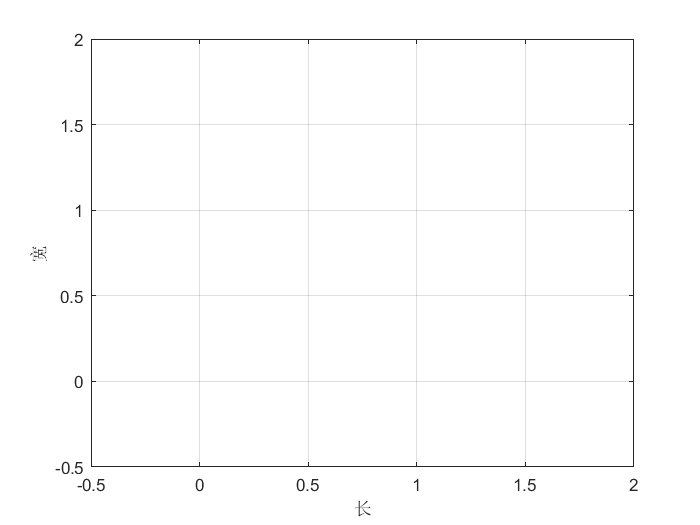

plot(x(1),x(2))
xlabel('长')
ylabel('宽')
grid on